clear all
load ARTEMIS.mat;
start=100;%Definisci l'istante iniziale
N=5; %Time horizon
u=[];
%definisci le opzioni per l'optimisation
opts=optimoptions('fmincon','algorithm','sqp','MaxFunctionEvaluations',1e5,'Display','none');
    
%Simuli su finestre di 5 secondi per avere un'idea di come simulerebbe nel
%lungo periodo senza che ci metta 200 ore ogni volta. Non è MPC è solo per
%vedere i risultati pratici
for j=1:18
    %Estrai i sottovettori e ridefinisci gli handle per i sottovettori.
    %Stavolta la funzione di costo è calcolata tutta in una volta. Bisogna
    %rivedere la funzione di costo bene
    speed=ARTEMIS(1,start-1+j*N:start+N-1+j*N);
    acceleration=ARTEMIS(2,start-1+j*N:start+N-1+j*N);
    gear=ARTEMIS(3,start-1+j*N:start+N-1+j*N);
    
    StateUpdate=@(input,cur_SOC,i)hev_MPC(speed(i),acceleration(i),gear(i),cur_SOC,input);
    FullStateUpdate=@(u)full_horizon(u,0.55,StateUpdate);
    nonlinconstr_h=@(u)nonlinconstr(u,0.55,StateUpdate);
    %calcoli la u ottima sull'orizzonte dei 5 secondi
    tic
    %salvi la u per poi vedere il risultato complessivo
    u=[u;fmincon(FullStateUpdate,0.5*ones(N,1),[],[],[],[],...
        -1*ones(N,1),ones(N,1),nonlinconstr_h,opts)];
    toc
end

Elapsed time is 2.572227 seconds.
Elapsed time is 1.895038 seconds.
Elapsed time is 1.181420 seconds.
Elapsed time is 1.881168 seconds.
Elapsed time is 2.526065 seconds.
Elapsed time is 0.644096 seconds.
Elapsed time is 4.415503 seconds.
Elapsed time is 2.079378 seconds.
Elapsed time is 0.374952 seconds.
Elapsed time is 1.047838 seconds.
Elapsed time is 3.184519 seconds.
Elapsed time is 2.147575 seconds.
Elapsed time is 1.753733 seconds.
Elapsed time is 3.867320 seconds.
Elapsed time is 1.815435 seconds.
Elapsed time is 0.603757 seconds.
Elapsed time is 0.386378 seconds.
Elapsed time is 0.381248 seconds.


%Vedi i risultati utilizzando la u trovata nell'intero orizzonte
speed=ARTEMIS(1,start:start+N-1+j*N);
acceleration=ARTEMIS(2,start:start+N-1+j*N);
gear=ARTEMIS(3,start:start+N-1+j*N);
StateUpdate=@(input,cur_SOC,i)hev_MPC(speed(i),acceleration(i),gear(i),cur_SOC,input);
FullStateUpdate=@(u)full_horizon(u,0.55,StateUpdate);
[cost,I,SOC,mf,Te_max,Tm_min,Tm_max,Te,Tm]=FullStateUpdate(u);
sum(mf)

ans = 0.0035

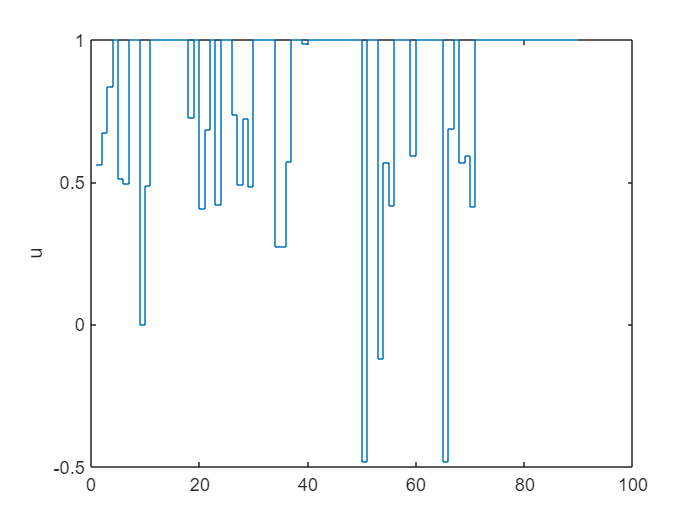

stairs(u)
ylabel('u')

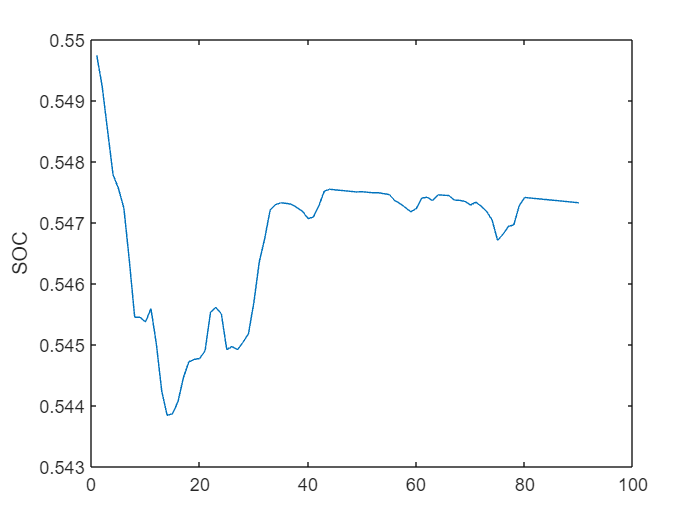

plot(SOC)
ylabel('SOC')

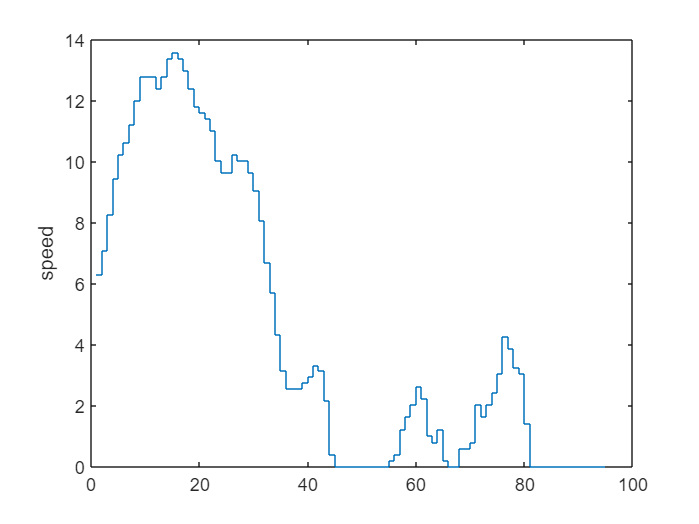

stairs(speed)
ylabel('speed')

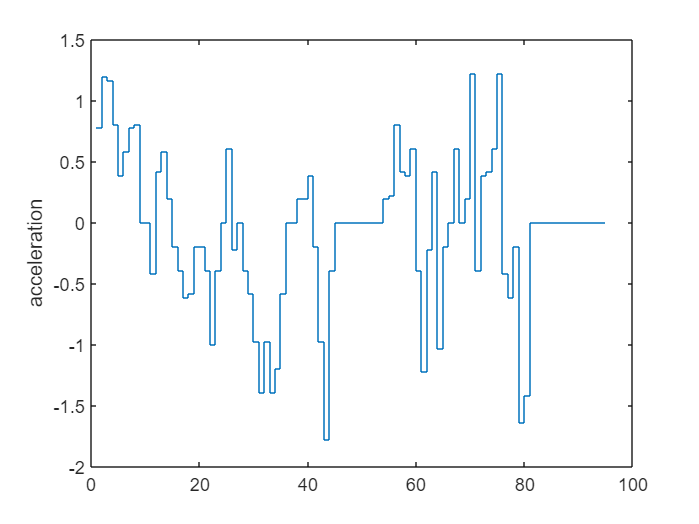

stairs(acceleration)
ylabel('acceleration')

u=[u;fmincon(FullStateUpdate,0.5*ones(N,1),[],[],[],[],-1*ones(N,1),ones(N,1),[],opts)];